# Example using generic control input

We use a generic control input, as described in [json schema documentation](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonSchemas/GenericControl.schema.json).

## Input setup

We load material parameter input parameters

jsonstruct_material = parseBattmoJson(fullfile('ParameterData', ...
                                               'BatteryCellParameters', ...
                                               'LithiumIonBatteryCell', ...
                                               'lithium_ion_battery_nmc_graphite.json'));

We load geometry parameter input parameters

jsonstruct_geometry = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'geometryChen.json'));

We load the generic control parameter we want to use

jsonstruct_control  = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'generic_step_control_simple_example.json'));

We print it to command window

viewStruct(jsonstruct_control)

{
  "Control": {
    "controlPolicy": "Generic",
    "controlsteps": [
      {
        "controltype": "rest",
        "termination": {
          "quantity": "time",
          "value": 4000
        },
        "timeStepSize": 600
      },
      {
        "controltype": "current",
        "value": 1,
        "direction": "discharge",
        "termination": {
          "quantity": "voltage",
          "value": 3,
          "comparison": "below"
        },
        "timeStepSize": 600
      },
      {
        "controltype": "voltage",
        "value": 3,
        "termination": {
          "value": 0.0001,
          "quantity": "current",
          "comparison": "absolute value below"
        },
        "timeStepSize": 600
      },
      {
        "controltype": "current",
        "value": 1,
        "direction": "charge",
        "termination": {
          "quantity": "voltage",
          "value": 4,
          "comparison": "above"
        },
        "timeStepSize": 600
      },
      {
    

We remove the fields that are not relevant for this example. This is done to simplify the input parameters and focus on the relevant aspects of the model.

jsonstruct_material = removeStructFields(jsonstruct_material              , ...
                                             {'Control', 'DRate'}             , ...
                                             {'Control', 'controlPolicy'}     , ...
                                             {'Control', 'upperCutoffVoltage'}, ...
                                             {'Control', 'rampupTime'}        , ...
                                             {'Control', 'lowerCutoffVoltage'});

We merge all the input structures

jsonstruct = mergeStructs({jsonstruct_material, ...
                               jsonstruct_geometry, ...
                               jsonstruct_control});

We do not include thermal effects and the current collectors in this example to simplify the model.

jsonstruct.use_thermal = false;
jsonstruct.include_current_collectors = false;

We run the simulation

output = runBatteryJson(jsonstruct);

Solving timestep 1: Solving timestep 2: 00 Seconds                                             -> 1200 Seconds
Solving timestep 3: 200 Seconds                                       -> 1800 Seconds
Solving timestep 4: 800 Seconds                                       -> 2400 Seconds
Solving timestep 5: 400 Seconds                                        -> 3000 Seconds
Solving timestep 6: 000 Seconds                                         -> 1 Hour
Solving timestep 7:  Hour                                             -> 1 Hour, 600 Seconds
Solving timestep 8:  Hour, 600 Seconds                                -> 1 Hour, 1200 Seconds
Solving timestep 9:  Hour, 1200 Seconds                               -> 1 Hour, 1800 Seconds
Solving timestep 10:  Hour, 1800 Seconds                               -> 1 Hour, 2400 Seconds
Solving timestep 11:  Hour, 2400 Seconds                               -> 1 Hour, 3000 Seconds
Solving timestep 12:  Hour, 3000 Seconds                               -> 2 H

## Plotting

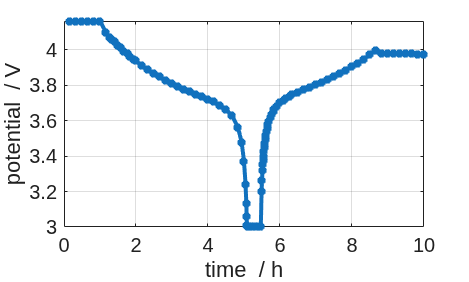

states = output.states;

E = cellfun(@(x) x.Control.E, states);
I = cellfun(@(x) x.Control.I, states);
time = cellfun(@(x) x.time, states);

figure
plot(time/hour, E, '*-', 'linewidth', 3);
grid on
xlabel 'time  / h';
ylabel 'potential  / V';

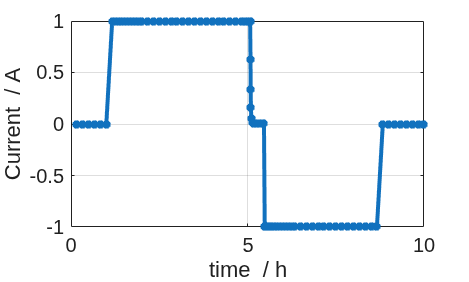


figure
plot(time/hour, I, '*-', 'linewidth', 3);
grid on
xlabel 'time  / h';
ylabel 'Current  / A';